# **Controlador Basado en Gain Scheduling. Modelo de Bergman.**

**Elaborado por: **Manuela María Muriel Tobar, David Andrés Ojeda Guzmán

**Universidad de Nariño**

En este proyecto se implementa un controlador basado en la técnica de  gain scheduling LQR, aplicado al modelo glucosa-insulina modificado de Bergman.  

Se evaluan métricas clínicas como tiempo en rango (TIR),  tiempo en hipoglucemia e hiperglucemia,  variabilidad glucémica (CV), Insulina promedio aplicada e insulina total aplicada. Finalmente se evaluan metricas de control como ISE, IAE, ITAE.

clear variables; close all; clc; 

[p1, p2, p3, p4, Ib, VI, G0, X0, I0, D0, Gsc0] = configurar_parametros(); 
%G0: Glucosa inicial, X0: Acción de insulina inicial
%I0: Insulina inicial, D0: Carga de glucosa ingerida inicialmente

horas_comidas = [7*60, 13*60, 20*60]; % 7am, 1pm, 8pm 

CHO_desayuno_g = 45;
CHO_almuerzo_g = 80;  % cantidad de carbohidratos en gramos
CHO_cena_g = 60;

D_comidas = @(t) definir_D_multi_mejorado(t, ...
    [CHO_desayuno_g, horas_comidas(1), 240], ...   
    [CHO_almuerzo_g, horas_comidas(2), 300], ...  
    [CHO_cena_g, horas_comidas(3), 240]);

get_glucose_reference = @(t_min) smooth_glucose_reference(t_min);% referencia a perseguir a lo largo del dia
get_IC_ratio = @(t_min) piecewise_IC_ratio(t_min); % ratio a lo largo del dia
get_basal_rate = @(t_min) piecewise_basal_rate(t_min); % tasa basal programada a lo largo del dia

 U_bolus_comida = @(t) 0; % no hay bolos preprogramados

G_op_points = [60, 80, 100, 140, 200, 300];% puntos de operacion

K_lqi_values = cell(size(G_op_points));

Q_base = diag([50, 5, 0.5, 5, 100]);
R_base = 0.1; 

 Para implementar gain scheduling, se seleccionan múltiples puntos de  operación representativos de diferentes niveles de glucosa (desde hipoglucemia hasta hiperglucemia severa). Para cada punto se linealiza  la planta y se diseña un controlador local.Se usan pesos distintos en las matrices Q y R dependiendo del punto, priorizando el control estricto cuando la glucosa está muy baja o muy alta.

En este caso, se eligió como variable de scheduling una combinación  ponderada entre: La glucosa actual del paciente (G) Y la referencia dinámica de glucosa ($G_{ref}$)  Se usa un promedio suavizado del tipo $G_{scheduling}$ = 0.7 * $G$ + 0.3 * $G_{ref}$. 

Esta elección tiene tres ventajas:

- Proporciona una transición más suave entre regiones de control.

- Mejora la estabilidad al evitar saltos abruptos en la ganancia. 

- permite que la acción de control se anticipe a la direccion del control y no reaccione unicamente ante el estado presente

El valor resultante de $G_{scheduling}$ se utiliza para interpolar entre los controladores diseñados para puntos específicos de operación.

%definición de varios puntos de operacion
% y aplicación de la tecnica de gain scheduling
for i = 1:length(G_op_points)% recorre todos los puntos de operacion
    G_op = G_op_points(i);
    %fprintf('  - Glucosa de operación: %g mg/dl\n', G_op);

    X_eq = 0; % no hay accion de insulina activa
    I_eq = Ib; % la insulina plasmatica esta en su nivel basal
    Gsc_eq = G_op; % se ha alcanzado el punto de operacion
    
    % Matrices A y B linealizadas
    A_lin_lqi = [
        -(p1 + X_eq), -G_op,      0,          0,          0;
        0,            -p2,        p3,         0,          0;
        0,            0,          -p4,        0,          0;
        1/5,          0,          0,          -1/5,       0;
        1,            0,          0,          0,          0   
    ];
    B_lin_lqi = [0; 0; 1/VI; 0; 0];

    Q = Q_base;% se toman valores base
    R = R_base;% se ajustan dependiendo del nivel de glucosa

    if G_op < 80 % Hipoglucemia 
        Q(1,1) = 20;
        Q(5,5) = 50;  
        R = 0.5;    % se penaliza el inyectar mas insulina  
    elseif G_op > 180 % Hiperglucemia 
        Q(1,1) = 100; 
        Q(5,5) = 200; 
        R = 0.05; % hay penalizacion minima a la insulina (correccion agresiva)
    end

    [K_lqi, ~, ~] = lqr(A_lin_lqi, B_lin_lqi, Q, R); % implementa el LQR
    K_lqi_values{i} = K_lqi; % se lo almacena para ser usado en el gain scheduling
    
    %fprintf('    -> K_LQI = [%s]\n', num2str(K_lqi, '%.3f '));
end

% Simulación
tspan = 0:1:24*60;
y0 = [G0; X0; I0; D0; Gsc0; 0];

[t_sim, Y_sim] = ode45(@(t,y) modelo_lqi_corregido(t, y, p1, p2, p3, p4, Ib, VI, ...
    get_basal_rate, U_bolus_comida, D_comidas, get_glucose_reference, G_op_points, K_lqi_values), ...
    tspan, y0);

G = Y_sim(:,1);
I = Y_sim(:,3);
Integral_Error = Y_sim(:,6);

% Para análisis y visualización
U_total_applied = zeros(size(t_sim));
actual_references = zeros(size(t_sim));
actual_IC_ratios = zeros(size(t_sim));
actual_basal_rates = zeros(size(t_sim));
control_gains_used = zeros(size(t_sim));

for k = 1:length(t_sim)
    current_t = t_sim(k);
    current_G = Y_sim(k,1);

    current_Gb = get_glucose_reference(current_t);
    actual_references(k) = current_Gb;
    actual_IC_ratios(k) = get_IC_ratio(current_t);
    actual_basal_rates(k) = get_basal_rate(current_t);

    % Gain scheduling usando referencia ponderada (variable de scheduling)
    G_for_scheduling = 0.7 * current_G + 0.3 * current_Gb;
    G_for_scheduling = max(min(G_for_scheduling, max(G_op_points)), min(G_op_points));% se restringe la variable dentro de los rangos de operacion

    K_interp_matrix = zeros(size(K_lqi_values{1}));% interpolacion entre los controladores
    for col = 1:size(K_lqi_values{1}, 2)           % adaptado al valor de la glucosa
        coeffs_for_col = cellfun(@(x) x(col), K_lqi_values);
        K_interp_matrix(col) = interp1(G_op_points, coeffs_for_col, G_for_scheduling, 'linear', 'extrap');
    end

    % Estados para LQR
    delta_G = current_G - current_Gb;
    delta_X = Y_sim(k,2) - 0;
    delta_I = Y_sim(k,3) - Ib;
    delta_Gsc = Y_sim(k,5) - current_Gb;
    delta_Ie = Y_sim(k,6);

    delta_x_lqi = [delta_G; delta_X; delta_I; delta_Gsc; delta_Ie];
    % calculo de la acción de control para la realimentacion del estado
    %se suma a la infusion basal constante
    U_delta = -K_interp_matrix * delta_x_lqi;

    %Lógica de corte hipoglucémico
    U_hypo_cutoff_threshold = 75   ;

    if current_G <= U_hypo_cutoff_threshold
        U_total_demanded_k = actual_basal_rates(k) * 0.5;
    else
        U_total_demanded_k = actual_basal_rates(k) + U_delta;
    end
    % se satura la maxima señal de control por seguridad
    U_max_injectable = 100;
    U_min_injectable = 0;

Para garantizar un control seguro, se incorporan los siguientes mecanismos:

- **Corte por hipoglucemia:** si $G$ ≤ 75 mg/dL.

- **Anti-windup**: si la insulina alcanza su límite (máximo o mínimo), y el error va en la misma dirección, se detiene la integración del error acumulado.

    U_total_applied(k) = max(min(U_total_demanded_k, U_max_injectable), U_min_injectable);
end
figure('Color','w', 'Position', [100 100 1200 800]);

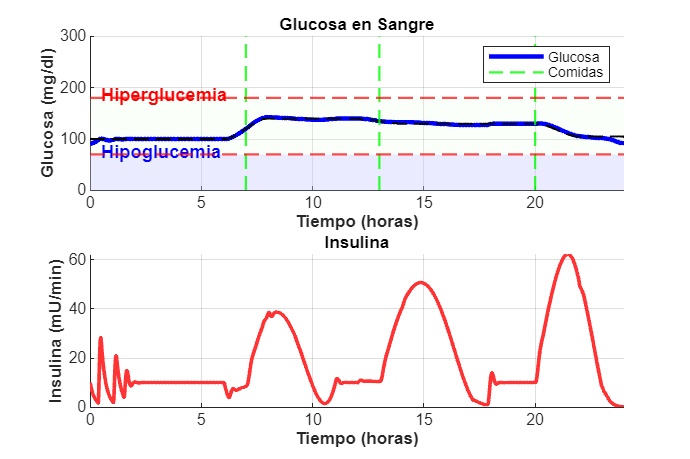

% ===== Glucosa en sangre =====
subplot(2,1,1);
hold on;
fill([t_sim/60; flipud(t_sim/60)], ...
    [70*ones(size(t_sim)); flipud(180*ones(size(t_sim)))], ...
    [0.9 1 0.9], 'EdgeColor', 'none', 'FaceAlpha', 0.2);

fill([t_sim/60; flipud(t_sim/60)], ...
    [zeros(size(t_sim)); flipud(min(G,70))], ...
    [0.8 0.8 1], 'EdgeColor', 'none', 'FaceAlpha', 0.4);

fill([t_sim/60; flipud(t_sim/60)], ...
    [180*ones(size(t_sim)); flipud(max(G,180))], ...
    [1 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.4);

h1 = plot(t_sim/60, G, 'b', 'LineWidth', 2.5);
for t_comida = horas_comidas/60
    h2 = xline(t_comida, '--g', 'LineWidth', 1.2, 'Alpha', 0.8);
end
legend([h1 h2], {'Glucosa', 'Comidas'}, 'Location','northeast');
h_ref = plot(t_sim/60, actual_references, 'Color', 'black', 'LineStyle', '--', 'LineWidth', 1.2);

yline(70, '--r', 'LineWidth', 1.2, 'Alpha', 0.7);
yline(180, '--r', 'LineWidth', 1.2, 'Alpha', 0.7);
text(0.5, 75, 'Hipoglucemia', 'Color', 'blue', 'FontWeight','bold');
text(0.5, 185, 'Hiperglucemia ', 'Color', 'red', 'FontWeight','bold', 'HorizontalAlignment','left');

xlabel('Tiempo (horas)', 'FontWeight','bold');
ylabel('Glucosa (mg/dl)', 'FontWeight','bold');
title('Glucosa en Sangre', 'FontWeight','bold');
xlim([0 24]); ylim([0 300]);
legend([h1 h2], {'Glucosa', 'Comidas'}, 'Location','northeast');
grid on;

% ===== Insulina =====
subplot(2,1,2);
hold on;
plot(t_sim/60, I, 'Color',[1 0.2 0.2], 'LineWidth', 2);
%plot(t_sim/60, U_total_applied, 'Color', [0.5 0.5 0.5], 'LineStyle', '--', 'LineWidth', 1.5);
xlabel('Tiempo (horas)', 'FontWeight','bold');
ylabel('Insulina (mU/min)', 'FontWeight','bold');
title('Insulina', 'FontWeight','bold');

xlim([0 24]); grid on;

total_insulina= trapz(t_sim, I);

Insulina total aplicada: 


disp('Insulina total aplicada: ');

   2.7801e+04

  mU


disp(total_insulina);disp('  mU');
D_total = t_sim(end)- t_sim(1);

mean_insulina= total_insulina/D_total;

Insulina promedio aplicada: 


disp('Insulina promedio aplicada: ');

   19.3060

  mU


disp(mean_insulina);disp('  mU');

% ===== Métricas de control glucemico =====

time_in_range = sum((G >= 70) & (G <= 180)) / length(G) * 100;
time_below_70 = sum(G < 70) / length(G) * 100;
time_above_180 = sum(G > 180) / length(G) * 100;
mean_glucose = mean(G);
glucose_cv = std(G) / mean(G) * 100;

fprintf('\nRESULTADOS\n');


RESULTADOS


fprintf('Tiempo en rango (70-180): %.1f%%\n', time_in_range);

Tiempo en rango (70-180): 100.0%


fprintf('Tiempo en hipoglucemia: %.1f%%\n', time_below_70);

Tiempo en hipoglucemia: 0.0%


fprintf('Tiempo en hiperglucemia: %.1f%%\n', time_above_180);

Tiempo en hiperglucemia: 0.0%


fprintf('Glucosa promedio: %.1f mg/dl\n', mean_glucose);

Glucosa promedio: 120.2 mg/dl


fprintf('Coeficiente de variación: %.1f%%\n', glucose_cv);

Coeficiente de variación: 13.8%


function ref_val = smooth_glucose_reference(t_min)
    t_hour = mod(t_min / 60, 24); 
    %funciones sigmoideas
    if t_hour >= 0 && t_hour < 6
        ref_val = 100;
    elseif t_hour >= 6 && t_hour < 8
        alpha = (t_hour - 6) / 2; % 0 a 1 en 2 horas
        ref_val = 100 + (140 - 100) * (3*alpha^2 - 2*alpha^3); % 
    elseif t_hour >= 8 && t_hour < 12
        ref_val = 140;
    elseif t_hour >= 12 && t_hour < 14 % Transición gradual
        alpha = (t_hour - 12) / 2;
        ref_val = 140 + (130 - 140) * (3*alpha^2 - 2*alpha^3);


ÍNDICES DE DESEMPEÑO


    elseif t_hour >= 14 && t_hour < 20

IAE Norm: 1.40


        ref_val = 130;

ISE Norm :  5.91


    elseif t_hour >= 20 && t_hour < 22 % Transición gradual

ITAE Norm:  1318.37


        alpha = (t_hour - 20) / 2;
        ref_val = 130 + (105 - 130) * (3*alpha^2 - 2*alpha^3);
    else % 22 a 24
        ref_val = 105;
    end
end

function ic_ratio_val = piecewise_IC_ratio(t_min)
    t_hour = mod(t_min / 60, 24);

    if t_hour >= 0 && t_hour < 8 
        ic_ratio_val = 11; 
    elseif t_hour >= 8 && t_hour < 12 
        ic_ratio_val = 8;  
    elseif t_hour >= 12 && t_hour < 20 
        ic_ratio_val = 10; 
    else 
        ic_ratio_val = 11.5; 
    end
end

%tasa basal a lo largo del dia
function basal_rate_val = piecewise_basal_rate(t_min)
    t_hour = mod(t_min / 60, 24);

    if t_hour >= 0 && t_hour < 4 
        basal_rate_val = 0.08; 
    elseif t_hour >= 4 && t_hour < 12 
        basal_rate_val = 0.15; 
    elseif t_hour >= 12 && t_hour < 20 
        basal_rate_val = 0.12; 
    else 
        basal_rate_val = 0.10; 
    end
end

function [p1, p2, p3, p4, Ib, VI, G0, X0, I0, D0, Gsc0] = configurar_parametros()
    p1 = 0.03; p2 = 0.02; p3 = 4.5e-5; p4 = 0.08;
    Ib = 10; VI = 12; 
    G0 = 90; X0 = 0; I0 = Ib; D0 = 0; Gsc0 = G0; 
end

function D_output = definir_D_multi_mejorado(t, varargin)
    D_output = 0;
    for i = 1:size(varargin,2)
        carga_g = varargin{i}(1);
        t_ini = varargin{i}(2);
        dur = varargin{i}(3);

        FACTOR_MG_POR_G_CHO_EN_PLASMA = 1000 / 50; % 1 gramo de carbohidrato corresponde a 20 mg/dL de glucosa
        carga_mg_equivalente = carga_g * FACTOR_MG_POR_G_CHO_EN_PLASMA; 

        if t >= t_ini && t <= t_ini + dur
            tau_abs = (t - t_ini) / dur;
            profile_shape = tau_abs.^2 .* (1 - tau_abs).^2; 
            normalizacion_factor_profile = 1/30; 

            D_output = D_output + (carga_mg_equivalente / dur) * (profile_shape / normalizacion_factor_profile);
        end
    end
end

function dydt = modelo_lqi_corregido(t, y, p1, p2, p3, p4, Ib, VI, ...
    get_basal_rate_fcn, U_bolus_comida, D_comidas, get_glucose_reference_fcn, G_op_points, K_lqi_values)

    G = y(1); X = y(2); I = y(3); Dt = y(4); Gsc = y(5); Ie = y(6);
    
    % Límites
    U_max_injectable = 100; 
    U_min_injectable = 0; 

    Gb_current = get_glucose_reference_fcn(t); 
    basal_rate_current = get_basal_rate_fcn(t);

    % Gain scheduling
    G_filtered = 0.8 * G + 0.2 * Gb_current; 
    current_G_for_interp = max(min(G_filtered, max(G_op_points)), min(G_op_points)); 
    
    K_interp_matrix = zeros(size(K_lqi_values{1}));
    for col = 1:size(K_lqi_values{1}, 2)
        coeffs_for_col = cellfun(@(x) x(col), K_lqi_values);
        K_interp_matrix(col) = interp1(G_op_points, coeffs_for_col, current_G_for_interp, 'linear', 'extrap');
    end

    X_eq_current = 0;
    I_eq_current = Ib; 
    Gsc_eq_current = Gb_current; 

    delta_x_lqi = [
        G - Gb_current;
        X - X_eq_current;
        I - I_eq_current;
        Gsc - Gsc_eq_current;
        Ie
    ];
    
    U_delta = -K_interp_matrix * delta_x_lqi; 
    
    %Umbral de corte en hipoglucemia
    U_hypo_cutoff_threshold = 70;
    
    if G <= U_hypo_cutoff_threshold 
        U_total_from_controller = basal_rate_current * 0.3; 
        dIedt = 0; % Detener integración
    else
        U_total_from_controller = basal_rate_current + U_bolus_comida(t) + U_delta; 
        
        %Anti-windup 
        error_current = G - Gb_current;
        
        stop_integration = false;
        
        % Detiene la integral del error
        if (U_total_from_controller > U_max_injectable && error_current > 0)
            stop_integration = true;
        elseif (U_total_from_controller < U_min_injectable && error_current < 0)
            stop_integration = true;
        end
        
        % También detener si la integral es muy grande
        if abs(Ie) > 1000 && sign(Ie) == sign(error_current)
            stop_integration = true;
        end
        
        if stop_integration
            dIedt = 0;
        else
            dIedt = error_current;
        end
    end
    
    U_total = max(min(U_total_from_controller, U_max_injectable), U_min_injectable);
    
    D_current = D_comidas(t);   

    dGdt = -(p1 + X)*G + p1*Gb_current + D_current; 
    dXdt = -p2*X + p3*(I - Ib);
    dIdt = -p4*I + U_total/VI; 
    dDdt = 2*Dt; 
    dGscdt = (1/5)*(G - Gsc);
    
    dydt = [dGdt; dXdt; dIdt; dDdt; dGscdt; dIedt];
end

Error_LQI = actual_references - G;

abs_error_lqi = abs(Error_LQI);
squared_error_lqi = Error_LQI.^2;
time_weighted_abs_error_lqi = t_sim .* abs_error_lqi;

% Integración con trapz
IAE_LQI = trapz(t_sim, abs_error_lqi);
ISE_LQI = trapz(t_sim, squared_error_lqi);
ITAE_LQI = trapz(t_sim, time_weighted_abs_error_lqi);

% Mostrar resultados
fprintf('\nÍNDICES DE DESEMPEÑO\n');
fprintf('IAE Norm: %.2f\n', IAE_LQI/1440);
fprintf('ISE Norm :  %.2f\n', ISE_LQI/1440);
fprintf('ITAE Norm:  %.2f\n', ITAE_LQI/1440);